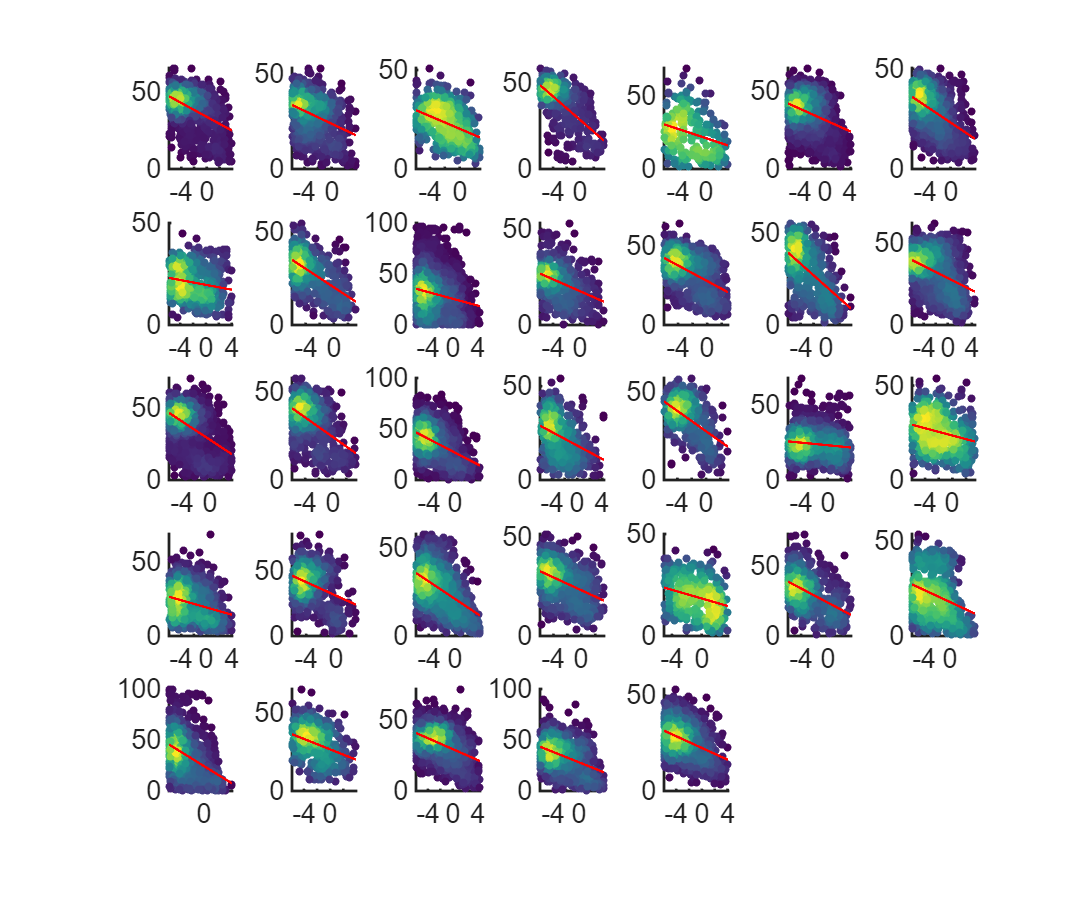

clc;clear;close all;
subG = {'sub-0001', 'sub-0002', 'sub-0003', 'sub-0004', 'sub-0005', ...
    'sub-0007', 'sub-0008', 'sub-0009', 'sub-0010', 'sub-0011', ...
    'sub-0012', 'sub-0013', 'sub-0014', 'sub-0015', 'sub-0016', ...
    'sub-0017', 'sub-0019', 'sub-0020', 'sub-0021', 'sub-0022', ...
    'sub-0023', 'sub-0028', 'sub-0029', 'sub-0031', 'sub-0033', ...
    'sub-0034', 'sub-0035', 'sub-0036', 'sub-0039', 'sub-0046', ...
    'sub-0047', 'sub-0050', 'sub-0052', 'sub-0054', 'sub-0062', ...
    'sub-0063', 'sub-0066', 'sub-0067', 'sub-0074', 'sub-0077', ...
    'sub-0087', 'sub-0089', 'sub-0092', 'sub-0093', 'sub-0094', ...
    'sub-0113', 'sub-0115'};
load(fullfile('step2_fiberTrack', ...
    'FiberMatrix_ncount_length_qa_allsubject.mat'), 'fiberCount');
load(fullfile('step4_IEDtw_polyfit_TD6d0', 'IEDtw_meth-None_TD-6d0.mat'));
figure('Units', 'centimeters', 'Position', [5, 5, 36, 30]);
N = 0;
for nS = 1:length(subG)
    subID = subG{nS};
    fibN = fiberCount{nS};
    if isempty(fibN)
        continue;
    end
    IEDtwD = IEDtw(nS).indirectTransferDelayMatrix;
    IEDtwR = IEDtw(nS).indirectTransferRateMatrix;
    Mask = IEDtwR;
    Mask = Mask - diag(diag(Mask));
    Mask(isnan(Mask)) = 0;
    Mask(Mask<0.1) = 0; 
    Mask(fibN==0) = 0;
    IEDtwD = IEDtwD(Mask>0);
    fibN = fibN(Mask>0);
    fibN = log(fibN);
    [polyModel, Curve, Ftest] = f_polyfit(fibN, IEDtwD, 1);
    N = N + 1; subplot(5, 7, N);
    f_densityScatter(fibN, IEDtwD, 2); hold on;
    plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
    set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 20, 'LineWidth', 2);
end